clear all;
filelist = [ "data_21-Mar-2025_10 motor1 19 to 31 rads.mat" ,"data_21-Mar-2025_10deazone mot1 pos.mat" , "data_21-Mar-2025_20 deadzone mot1 neg.mat" , "data_21-Mar-2025_20 motor0 1v.mat" , "data_21-Mar-2025_20 motor1 1v.mat" ,"data_21-Mar-2025_20 motor1 31 to 40rads 1.5v.mat"]

filelist = 1×6 string array
    "data_21-Mar-2025_10 motor1 19 to 31 rads.mat"    "data_21-Mar-2025_10deazone mot1 pos.mat"    "data_21-Mar-2025_20 deadzone mot1 neg.mat"    "data_21-Mar-2025_20 motor0 1v.mat"    "data_21-Mar-2025_20 motor1 1v.mat"    "data_21-Mar-2025_20 motor1 31 to 40rads 1.5v.mat"


exp_id = 1;
file = "lab3/data/motor1/" + filelist(exp_id)

file = "lab3/data/motor1/data_21-Mar-2025_10 motor1 19 to 31 rads.mat"

maskOpts = detectImportOptions("lab3/data/motor1/experiment_mask_"+exp_id+".csv");
mask = readtable("lab3/data/motor1/experiment_mask_"+exp_id+".csv",maskOpts);
load(file,"data")

fs=500;
ts = 1/fs;


## Divide time to see what frequencies happen at which time:

motorID = 1;
time = data(1,:);
y = data(2+motorID,:)*pi/2048;
u = data(4+motorID,:);
om = data(6,:);


slices = sliceTimeSeries(time,om);


% wrong_exp = [ 0 5.5 13 17.5 18 20];



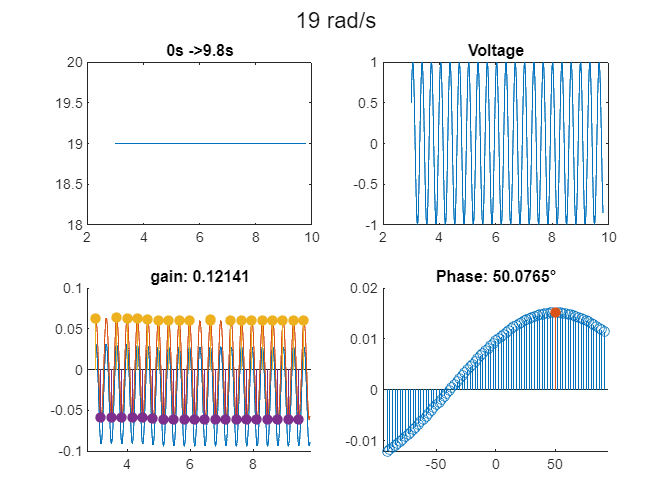

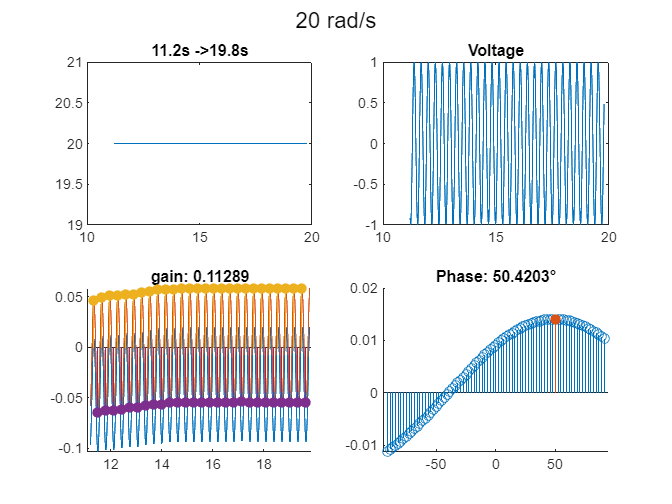

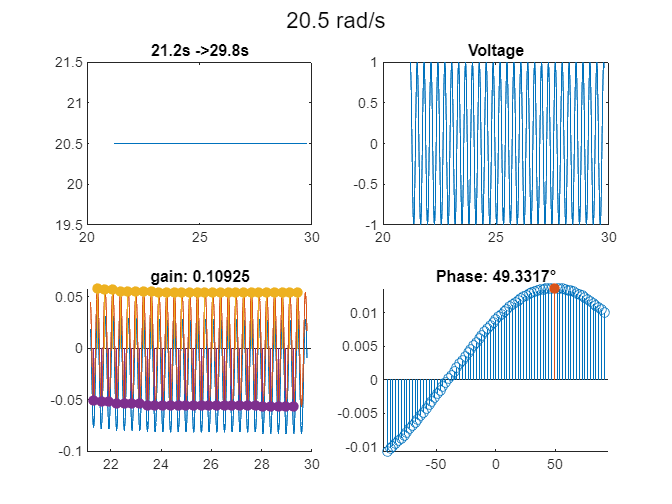

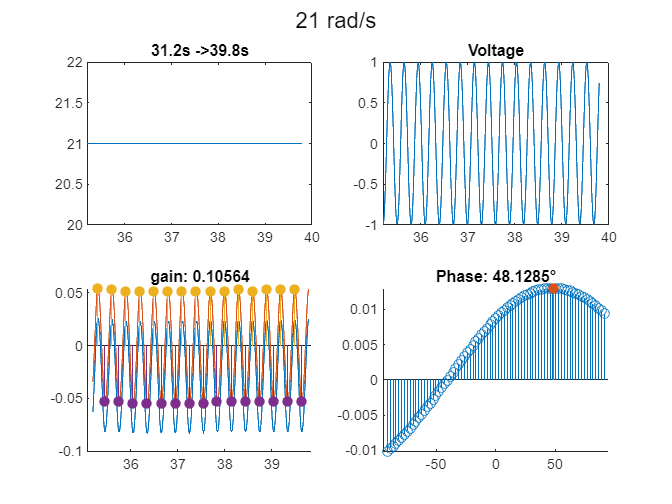

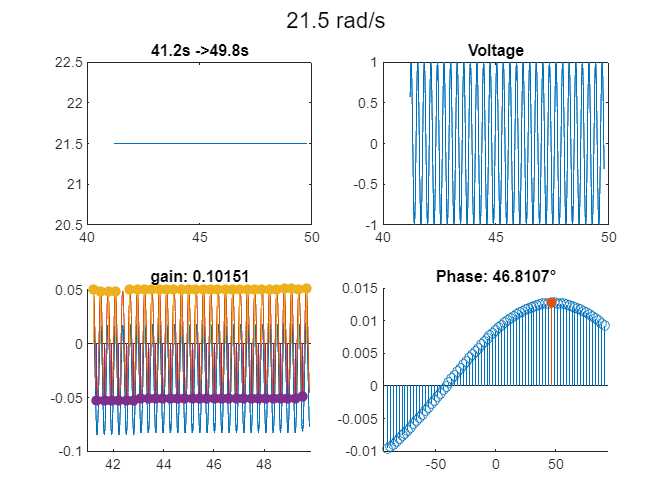

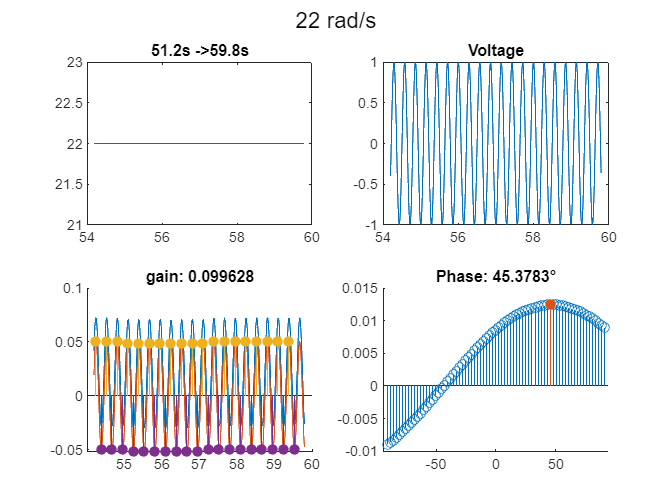

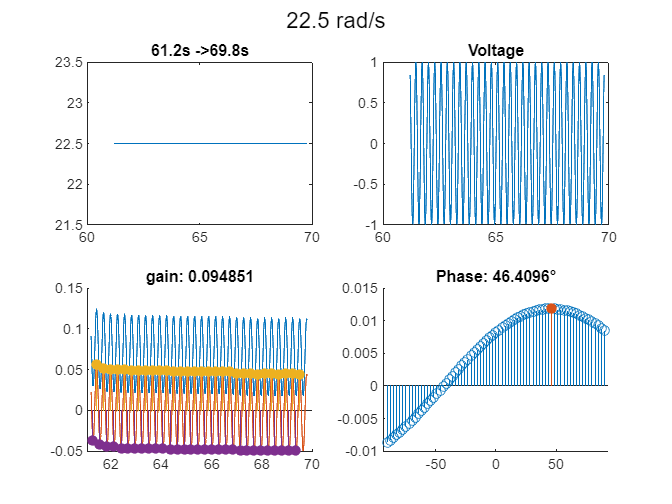

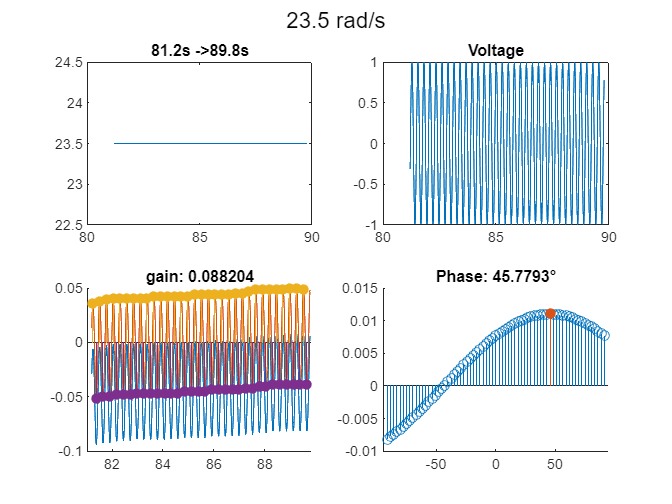

% for i = 2:2
for i = 1:size(slices,2)
    omega = slices{i}.f;
    % k = find(wrong_exp==omega);
if mask.enable(i) % it's one of the wrong experiments
    focus = slices{i};

    t_start_idx = time2index(focus.t_start+mask.t_start(i));
    t_end_idx = time2index(focus.t_end-mask.t_end(i));
   

    t_focus= time(t_start_idx:t_end_idx);
    om_focus= om(t_start_idx:t_end_idx);
    y_focus= y(t_start_idx:t_end_idx);
    u_focus= u(t_start_idx:t_end_idx);
    
    figure
    subplot(2,2,1)
        plot(t_focus,om_focus)
        title(focus.t_start + "s ->" + focus.t_end + "s")
    subplot(2,2,2)
        plot(t_focus,u_focus)
        title("Voltage")
    subplot(2,2,[3 4])
     [phase, gain] = SweepAnalysis(t_focus,u_focus, y_focus, omega);
    slices{i}.phase = phase;
    slices{i}.gain = gain;
    sgtitle(omega + " rad/s")
else
    slices{i}.phase = NaN;
    slices{i}.gain = NaN;
end
end

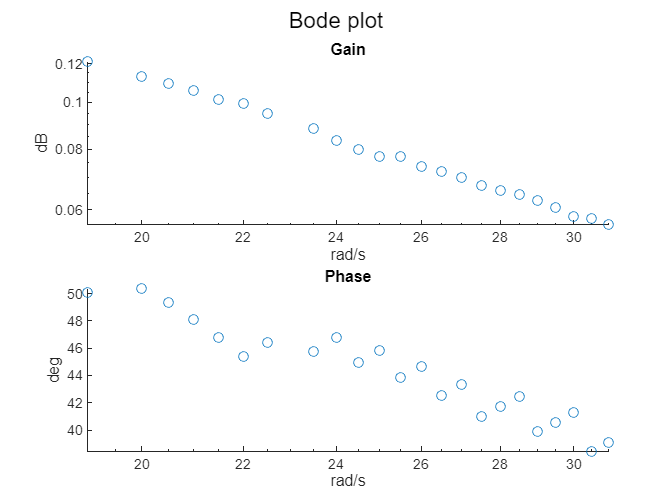

[freqs,phases, gains] = flatten(slices);



figure
sgtitle("Bode plot")
subplot(2,1,1)
scatter(freqs,gains)
yscale("log")
xscale("log")
title("Gain")
xlabel("rad/s")
ylabel("dB")

subplot(2,1,2)
scatter(freqs,rad2deg(phases))
xscale("log")
% ylim([0 90])
title("Phase")
xlabel("rad/s")
ylabel("deg")


function idx = time2index(time)
    idx = floor(time/0.002)+1;
end

function [freqs, phases, gain] = flatten(slices)
    freqs = [];
    phases = [];
    gain = [];
    for i = 1:size(slices,2)
        freqs(i) = slices{i}.f;
        phases(i) = slices{i}.phase;
        gain(i) = slices{i}.gain;

    end

end
